descarga de datos


datos = readtable('datos_personas.xlsx')

datos = 25000×4 table
    Index    Altura_m_    Peso_kg_     IMC  
    _____    _________    ________    ______

      1       1.6709       51.253     18.358
      2       1.8165        61.91     18.763
      3       1.7627       69.412     22.339
      4       1.7327       64.562     21.505
      5       1.7218       65.452     22.078
      6       1.7449       55.929     18.369
      7        1.773       64.181     20.417
      8       1.7784       61.898     19.572
      9       1.7247       50.971     17.135
     10       1.6963       54.734     19.022
     11       1.6888       57.811      20.27
     12       1.7176       51.774     17.549
     13       1.7349       56.976      18.93
     14       1.7048       55.548     19.113
     15       1.7343       52.656     17.506
     16       1.8057       63.502     19.475


grafico tres variables


alturas = datos.Altura_m_;
pesos = datos.Peso_kg_;
imcs = datos.IMC;


figure;
scatter3(alturas, pesos, imcs, 50, imcs, 'filled'); 
grid on;
xlabel('alturas');
ylabel('pesos');
zlabel('imcs');
title('Gráfico de dispersión 3D');
colorbar; 


% reducción a una variable entre altura y peso
base_altura_peso = [alturas, pesos];
[coeff, score, latent] = pca(base_altura_peso); % score contiene las componentes principales
primera_componente = score(:, 1); % primera
segunda_componente = score(:,2) %segunda

segunda_componente =    -0.0268
    0.0699
   -0.0183
   -0.0261
   -0.0411
    0.0258
    0.0159
    0.0318
    0.0283
   -0.0174


varianza_total = sum(latent)

varianza_total = 27.9790


proporcion_varianza = latent / sum(latent)  % Proporciones de varianza para componente 1 y 2 

proporcion_varianza =     0.9999
    0.0001




%la segunda componente es irrelevante

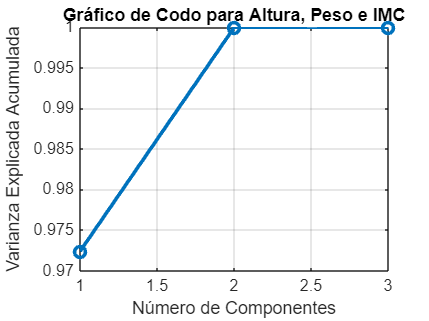

% Graficar la comparación de la primera componente con el IMC
figure;
scatter(primera_componente, imcs, 'filled');
xlabel('Primera Componente Principal (Altura y Peso)');
ylabel('IMC');
title('Primera Componente vs IMC');
grid on;


% Calcular correlaciones originales y transformadas
correlacion_peso_altura = corr(alturas,pesos);
correlacion_peso_imc = corr(pesos, imcs);
correlacion_altura_imc = corr(alturas, imcs);
correlacion_promedio = (correlacion_peso_altura+correlacion_peso_imc+correlacion_altura_imc)/3

correlacion_promedio = 0.3923


correlacion_transformada = corr(primera_componente, imcs)

correlacion_transformada = 0.7955


% comparar PCA entre las tres variables y solo altura/peso

datos_tres_variables = [alturas, pesos, imcs];
[coeff_3, score_3, latent_3] = pca(datos_tres_variables);

%variabilidades
varianza_total2 = sum(latent_3)

varianza_total2 = 30.3874


proporcion_varianza_nuevo = latent_3 / sum(latent_3)

proporcion_varianza_nuevo =     0.9724
    0.0276
    0.0000



%la tercera componente no explica nada directamente, y la segunda un 2.76%